clear
% Image path for Q1 image
ImagePath ='https://i.ibb.co/DKDpdpk/Q1-image.jpg';
[image, amp] =imread(ImagePath);

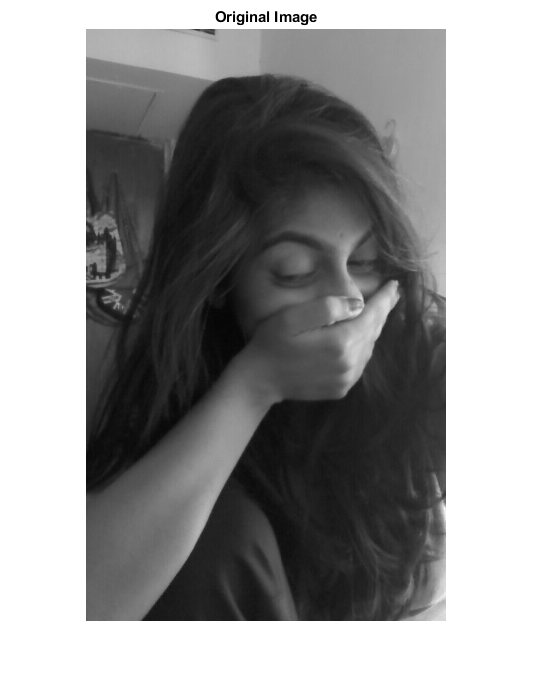

% size of image
gsImage = rgb2gray(image);
[rows,cols,~] = size(gsImage);
figure;
imshow(gsImage), title('Original Image')

Rotated images for 30 degrees


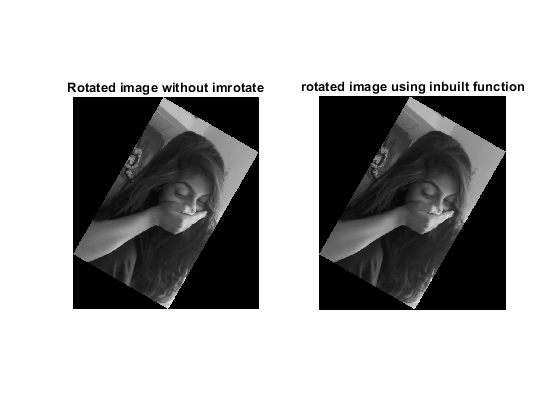

Rotated images for 60 degrees


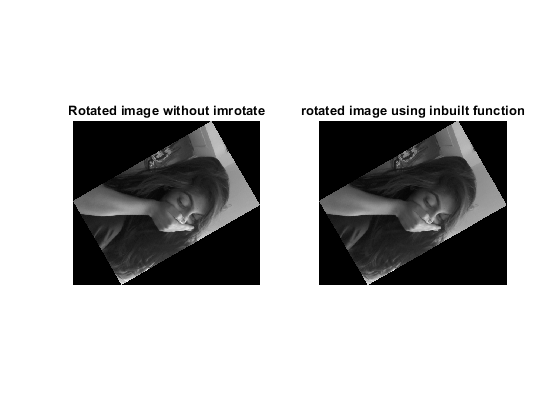


% Apply rotation matrix to 4 corners of the image 
corners = [-cols/2 rows/2; cols/2 rows/2; cols/2 -rows/2; -cols/2 -rows/2];

for n = 1:2
    if(n == 1)
        angle = 30;
    elseif(n == 2)
        angle = 60;
    end

    xRotatedImage =[];
    yRotatedImage =[];
    for i = 1:4
        x1 = corners(i,1)*cosd(angle) - corners(i,2)*sind(angle);
        y1 = corners(i,1)*sind(angle) + corners(i,2)*cosd(angle);
        xRotatedImage = [xRotatedImage,x1];
        yRotatedImage = [yRotatedImage,y1];
    end

    % forming a zero image
    HeightOfZeroMatrix = round(max(yRotatedImage) - min(yRotatedImage));
    WidthOfZeroMatrix = round(max(xRotatedImage)-min(xRotatedImage));
    ZeroImage = zeros(HeightOfZeroMatrix,WidthOfZeroMatrix);
    
    % calculating inverse and replacing pixels
    % Apply rotation inverse on points of the zero image formed 
    % Replace the pixel values with the values of the original image
    RotationInverse = [cosd(angle) sind(angle); -sind(angle) cosd(angle)];
    for i =round(min(xRotatedImage)):ceil(max(xRotatedImage))
        for j=round(min(yRotatedImage)):floor(max(yRotatedImage))
                   
            XnewPoints = [i;j];
            OriginalPoints = RotationInverse*XnewPoints;
          
            if(OriginalPoints(2) >-(rows/2)+1 && OriginalPoints(2)<=rows/2 && OriginalPoints(1) > -(cols/2)+1 && OriginalPoints(1) <=cols/2)
                x = floor(OriginalPoints(1)) + floor(cols/2);
                y = floor(OriginalPoints(2)) + floor(rows/2); 
                xnew = round(i + WidthOfZeroMatrix/2);
                ynew = round(j + HeightOfZeroMatrix/2);
                ZeroImage(ynew,xnew) = gsImage(y,x);
            end
        end
    end
 
    text = ['Rotated images for ', num2str(angle), ' degrees'];
    disp(text)
    figure;
    subplot(1,2,1),imshow(ZeroImage,[],'InitialMagnification','fit'),title('Rotated image without imrotate')
    drawnow; 
    
    % comparing using matlab inbuilt function. 
    matlabRotate = imrotate(gsImage,-angle);
    subplot(1,2,2),imshow(matlabRotate),title('rotated image using inbuilt function')
end